# Vaja 2

Naloga 1

%procent krvnih skupin
p0 = 0.47;
pA = 0.41;
pB = 0.09;
pAB = 0.03;

n = 30; %st ljudi
k = 0:n; 

PA = zeros(size(k));
PAB = zeros(size(k));
PneB = zeros(size(k));
P0aliAB = zeros(size(k));

for i = 1:length(k)
    PA(i) = nchoosek(n, k(i)) * (pA)^k(i) * (1 - pA)^(n - k(i)); %verjetnost za A
    PAB(i) = nchoosek(n, k(i)) * (pAB)^k(i) * (1 - pAB)^(n - k(i)); %verjetnost za AB
    PneB(i) = nchoosek(n, k(i)) * (1 - pB)^k(i) * (pB)^(n - k(i)); %verjetnost za ne B
    P0aliAB(i) = nchoosek(n, k(i)) * (pAB + p0)^k(i) * (1 - pAB - p0)^(n - k(i)); %verjetnost za 0 ali AB
end

tiledlayout('flow')
nexttile;
stem(k, PA)
title('st oseb z A')
xlabel('k')
ylabel('verjetnost')

nexttile;


stem(k, PAB)
title('st oseb z AB')
xlabel('k')
ylabel('verjetnost')

nexttile;

stem(k, PneB)
title('st oseb, ki nimajo B')
xlabel('k')
ylabel('verjetnost')

nexttile;
stem(k, P0aliAB)
title('st oseb z 0 ali AB')
xlabel('k')
ylabel('verjetnost')


EA = sum(k.*PA); %Vrh A
EAB = sum(k.*PAB); %Vrh AB
EneB = sum(k.*PneB); %Vrh ne B
E0aliAB = sum(k.*P0aliAB); %Vrh 0 ali AB

nexttile;
stem(EA, max(PA), 'r')
nexttile;
stem(EAB, max(PAB), 'r')
nexttile;
stem(EneB, max(PneB), 'r')
nexttile;
stem(E0aliAB, max(P0aliAB), 'r')

Naloga 2

pmRh = 0.15; % negativni rh
n = 100; %populacija
k = 0:20;

PBmRh = zeros(size(k));

for i = 1:length(k)
    PBmRh(i) = nchoosek(n,k(i))*(pB*pmRh)^k(i)*(1-pB*pmRh)^(n-k(i)); 
end


nexttile;
stem(k, PBmRh, 'o')
title('st B in rh-')
xlabel('k')
ylabel('verjetnost')

PpBmRh = (n*pB*pmRh).^k./factorial(k)*exp(-n*pB*pmRh);

nexttile;
plot(k,[PBmRh', PpBmRh'], 'o')
set(gca, 'yscal', 'log')
title('graf(k)')
xlabel('k')
ylabel('log(verjetnost)')
legend('Binom', 'Poisson')

rel = (PBmRh-PpBmRh)./PBmRh;

nexttile;
plot(k, rel, 'o')
title('rela napaka')
xlabel('k')
ylabel('% napaka')

k = 3;
n = 5:5:100;
PBmRh_n = zeros(size(n));

for i = 1:length(n)
    PBmRh_n(i) = nchoosek(n(i),k) * (pB * pmRh)^k.*(1 - pB * pmRh).^(n(i) - k); 
end

PpBmRh_n = (n * pB * pmRh).^k/factorial(k).*exp(-n * pB * pmRh);

rel_n = (PBmRh_n-PpBmRh_n)./PBmRh_n;

nexttile;
plot(n, [PBmRh_n', PpBmRh_n'], 'o')
set(gca, 'yscal', 'log')
title('graf(n)')
xlabel('n')
ylabel('log(verjetnost)')
legend('Binom', 'Poisson', 'Location','best')

nexttile;
plot(n, rel_n, 'o')
title('rela napaka')
xlabel('n')
ylabel('% napaka')

k = 3;
n = 100;
p = 0.01:0.01:0.25;
PBmRh_p = nchoosek(n,k)*(p).^k.*(1-p).^(n-k); 
PpBmRh_p = (n*p).^k/factorial(k).*exp(-n*p);

rel_p = (PBmRh_p-PpBmRh_p)./PBmRh_p;

nexttile;
plot(p, [PBmRh_p', PpBmRh_p'], 'o')
title('graf(p)')
xlabel('p')
ylabel('log(verjetnost)')
legend('Binom', 'Poisson')
set(gca, 'yscal', 'log')

nexttile;
plot(p, rel_p, 'o')
title('rela napaka')
xlabel('p')
ylabel('% napaka')

Naloga 3

T_GRA = 4550;
T_LIM = 2100;
T_MON = 350;
T_LEV = 7000;

V = 0.001;
k = 0:20;

P_LEV = (T_LEV * V).^k./factorial(k) * exp(-T_LEV * V);
P_GRA = (T_GRA * V).^k./factorial(k) * exp(-T_GRA * V);
P_LIM = (T_LIM * V).^k./factorial(k) * exp(-T_LIM * V);
P_MON = (T_MON * V).^k./factorial(k) * exp(-T_MON * V);

nexttile;
plot(k, [P_GRA', P_LIM', P_MON', P_LEV'], '-o')
xlabel('k')
ylabel('verjetnost')
legend('GRA','LIM','MON','LEV')
title('Poiss poraz')

l1_GRA = (k - T_GRA * V - 0.5) / sqrt(T_GRA * V);
l2_GRA = (k - T_GRA * V + 0.5) / sqrt(T_GRA * V);
l1_LIM = (k - T_LIM * V - 0.5) / sqrt(T_LIM * V);
l2_LIM = (k - T_LIM * V + 0.5) / sqrt(T_LIM * V);
l1_MON = (k - T_MON * V - 0.5) / sqrt(T_MON * V);
l2_MON = (k - T_MON * V + 0.5) / sqrt(T_MON * V);
l1_LEV = (k - T_LEV * V - 0.5) / sqrt(T_LEV * V);
l2_LEV = (k - T_LEV * V + 0.5) / sqrt(T_LEV * V);

Pg_GRA = (erf(l2_GRA / sqrt(2)) - erf(l1_GRA / sqrt(2))) / 2;
Pg_LIM = (erf(l2_LIM / sqrt(2)) - erf(l1_LIM / sqrt(2))) / 2;
Pg_MON = (erf(l2_MON / sqrt(2)) - erf(l1_MON / sqrt(2))) / 2;
Pg_LEV = (erf(l2_LEV / sqrt(2)) - erf(l1_LEV / sqrt(2))) / 2;

nexttile;
plot(k, [Pg_GRA', Pg_LIM', Pg_MON', Pg_LEV'],'-o')
xlabel('k')
ylabel('verjetnost')
legend('GRA', 'LIM', 'MON', 'LEV')
title('Gaussova porazdelitev')


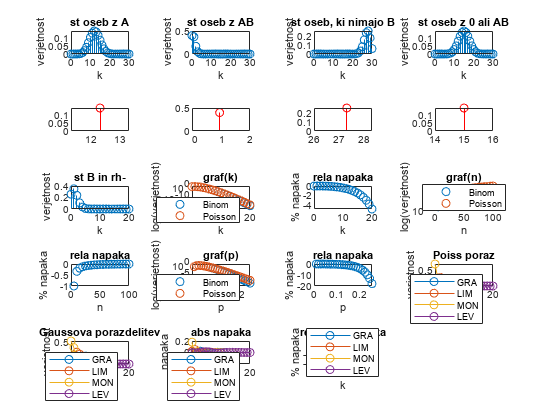


abs_GRA = P_GRA - Pg_GRA;
abs_LIM = P_LIM - Pg_LIM;
abs_MON = P_MON - Pg_MON;
abs_LEV = P_LEV - Pg_LEV;
rel_GRA = abs_GRA./P_GRA;
rel_LIM = abs_LIM./P_LIM;
rel_MON = abs_MON./P_MON;
rel_LEV = abs_LEV./P_LEV;

nexttile;
plot(k,[abs_GRA', abs_LIM', abs_MON', abs_LEV'],'-o')
xlabel('k')
ylabel('napaka')
legend('GRA', 'LIM', 'MON', 'LEV')
title('abs napaka')

nexttile;
plot(k, [rel_GRA', rel_LIM', rel_MON', rel_LEV'], '-o')
legend('GRA', 'LIM', 'MON', 'LEV', 'Location','best')
xlabel('k')
ylabel('% napaka')
title('relativna napaka')